close all; clear; clc;

# STv4 thrust curves #1

**file name**: STv4_TM15d.mlx

**keywords:** 

**date of test:** 20180824

**file created by:** 20180830, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** plots graphed from (1:3330) to offset the extended amount of time settling at the end of the test

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
%p = 0.00228519349876825;                  %[slugs/ft^3]
p = 0.002377;
% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('STv4_TM15d.mat');
time = STv4_TM15d(:,1);                       % [sec]
PWM = STv4_TM15d(:,2);                        % [micro sec]
Q = STv4_TM15d(:,4);                          % [ft.lbf]
T = STv4_TM15d(:,5);                          % [lbf]
Input_V = STv4_TM15d(:,6);                    % [Volts]
Input_A = STv4_TM15d(:,7);                    % [Amps]
rot_speed_rpm = STv4_TM15d(:,8);              % [RPM]
% convert to rad for calculation purposes
rot_speed_rad = rot_speed_rpm .* (pi/30);   % [rad/sec]
P_in_W = STv4_TM15d(:,9);                     % [Watts]
P_out_W = STv4_TM15d(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = STv4_TM15d(:,11);                 % [%]
Prop_Eff = STv4_TM15d(:,12);                  % [lbf/Watts]
Overall_Eff = STv4_TM15d(:,13);               % [lbf/Watts]  
ESC_Temp = STv4_TM15d(:,14);                  % [F]
Motor_Temp = STv4_TM15d(:,15);                % [F]

disk_loading = T ./ area;                     % [lb/sq.ft]

P_diff = P_in_W - P_out_W;                    % [Watts]

**Convert the following lines to code if this is a Settling Time script. Delete if not applicable**

Settling_time = STv4_TM15d(:,17); % [s]
Max_Acc = STv4_TM15d(:,18);      % [RPM]


## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

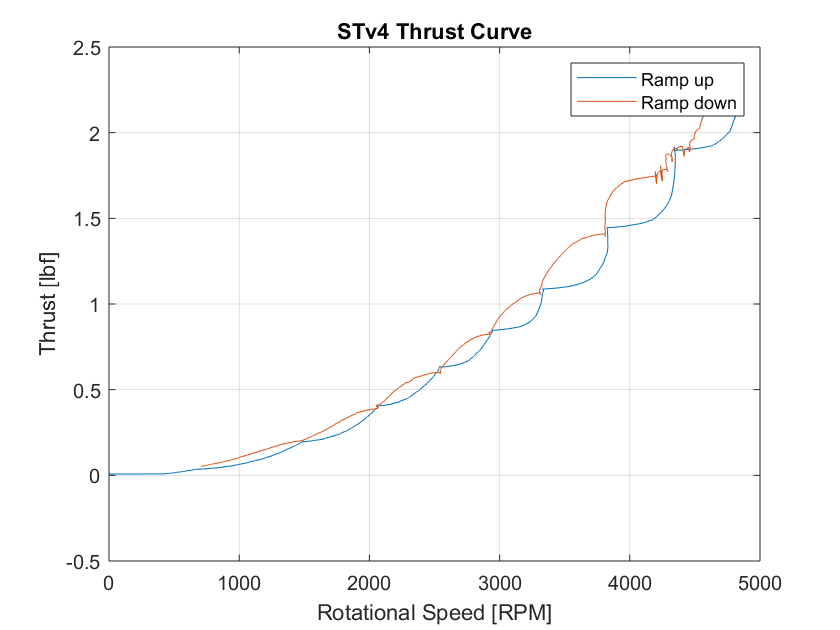

figure(1)
plot(rot_speed_rpm(1:900), T(1:900), rot_speed_rpm(900:3330), T(900:3330)); 
title('STv4 Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');
legend('Ramp up','Ramp down')

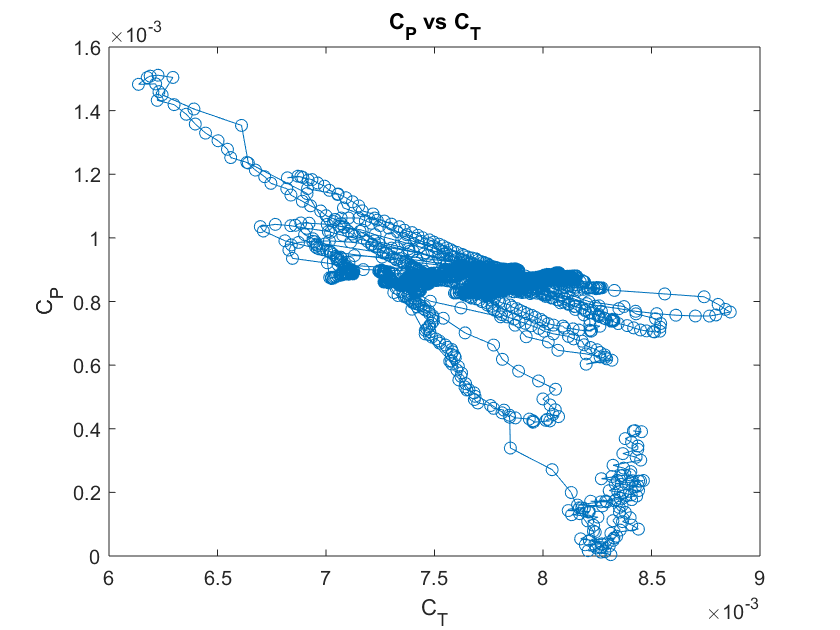


figure(2)
plot(C_T(200:3330), C_P(200:3330), 'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

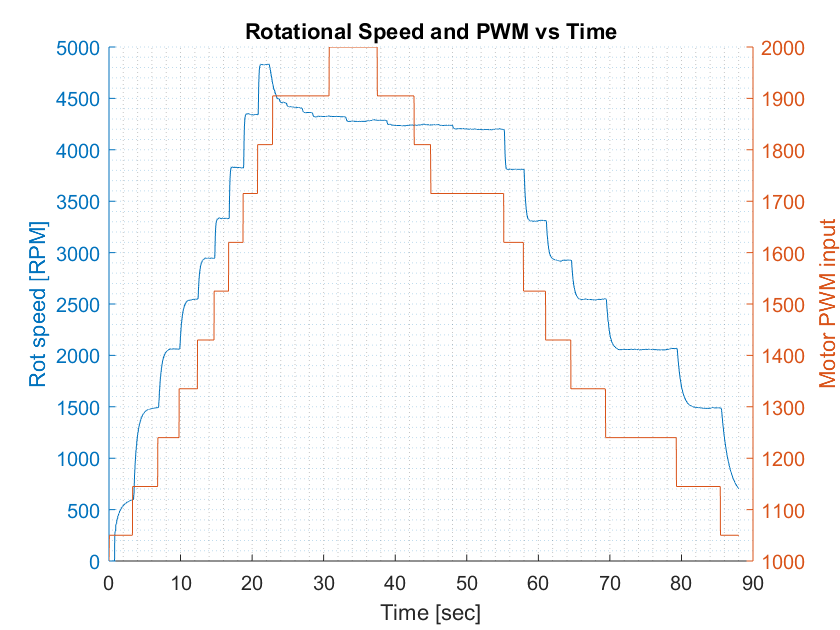


figure(3)
hold on
yyaxis left
plot(time(1:3330), rot_speed_rpm(1:3330));
ylabel('Rot speed [RPM]');
yyaxis right
plot(time(1:3330), PWM(1:3330));
ylabel('Motor PWM input');
title('Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

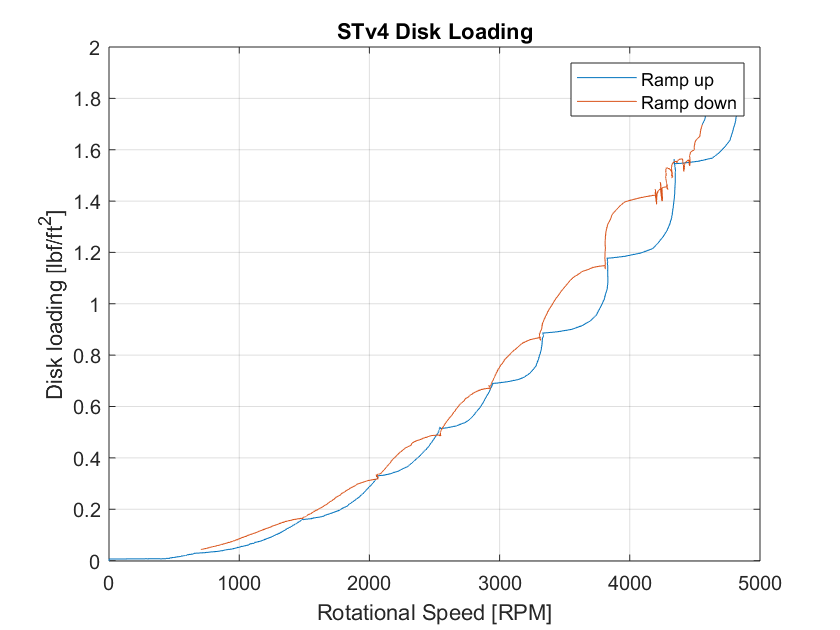


figure(4)
plot(rot_speed_rpm(1:900), disk_loading(1:900), rot_speed_rpm(900:3330), disk_loading(900:3330)); 
title('STv4 Disk Loading'); 
xlabel('Rotational Speed [RPM]'); ylabel('Disk loading [lbf/ft^2]');
legend('Ramp up','Ramp down'); grid('on');

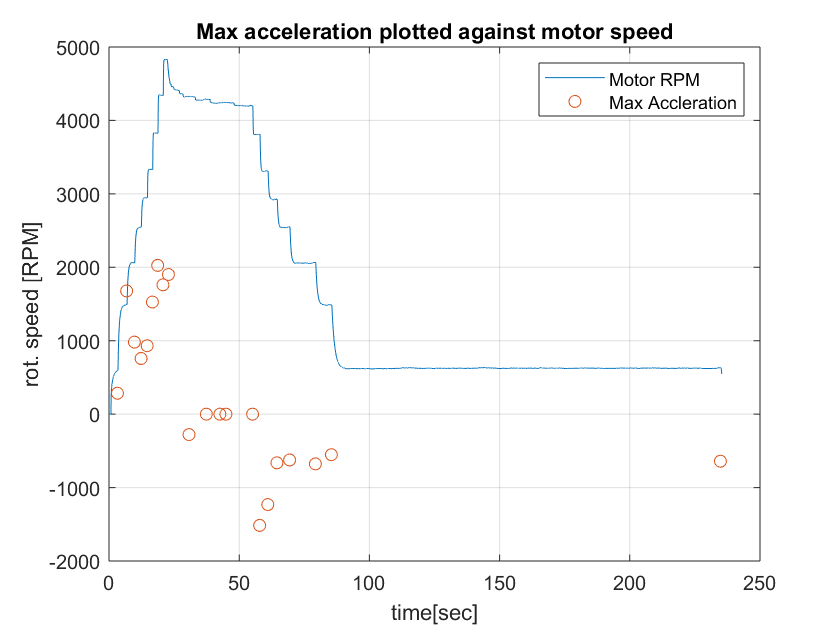



figure(5)
plot(time, rot_speed_rpm, time, Max_Acc, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');

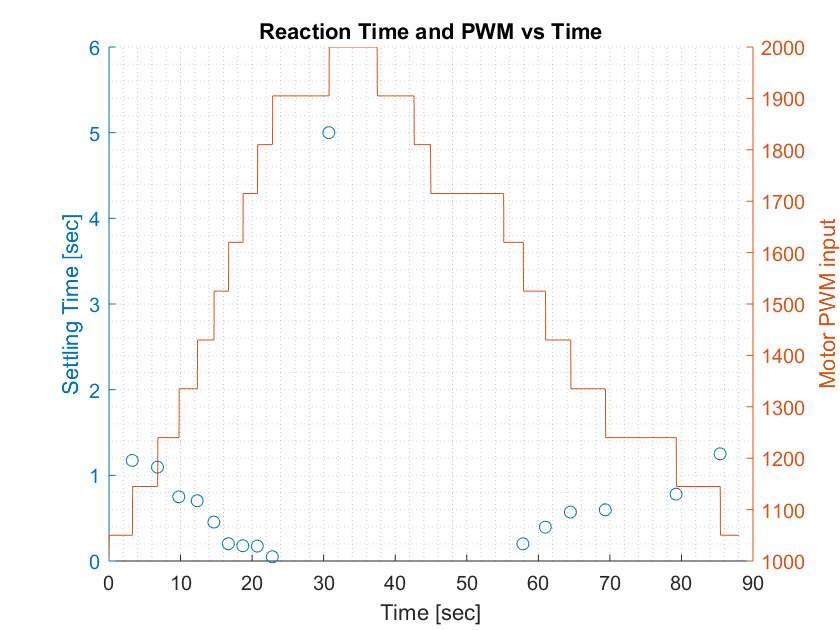


figure(6)
hold on
yyaxis left
plot(time(1:3330),Settling_time(1:3330), 'o-');
ylabel('Settling Time [sec]');
yyaxis right
plot(time(1:3330), PWM(1:3330));
ylabel('Motor PWM input');
title('Reaction Time and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

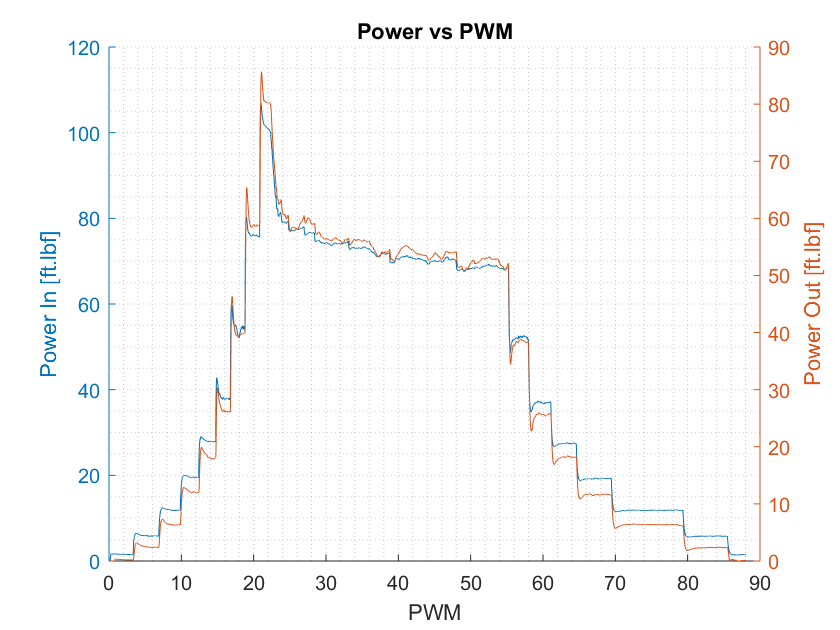


figure(7)
hold on
yyaxis left
plot(time(1:3330),P_in(1:3330));
ylabel('Power In [ft.lbf]');
yyaxis right
plot(time(1:3330), P_out(1:3330));
ylabel('Power Out [ft.lbf]');
title('Power vs PWM');
xlabel('PWM');
grid('minor');
hold off

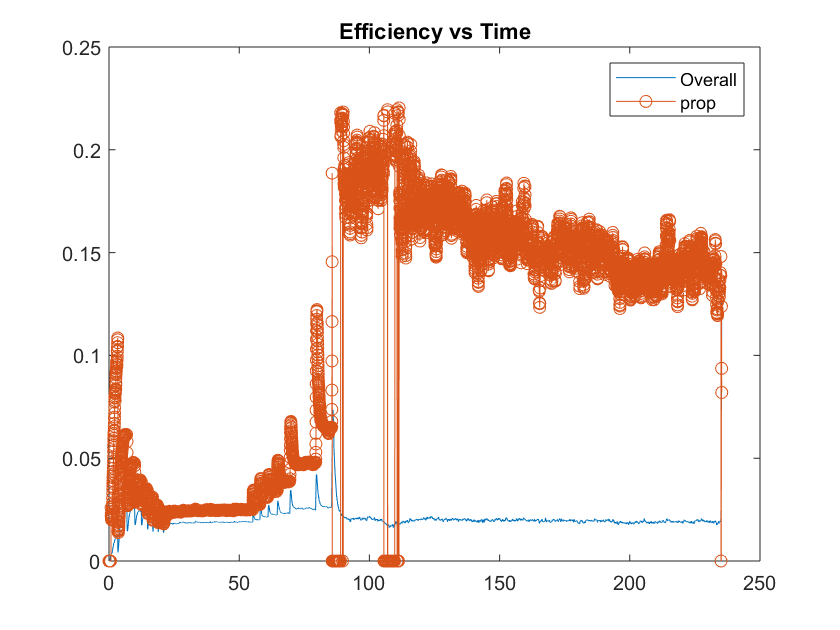


figure(8)
plot(time, Overall_Eff, time, Prop_Eff, 'o-');
legend('Overall', 'prop'); title('Efficiency vs Time');

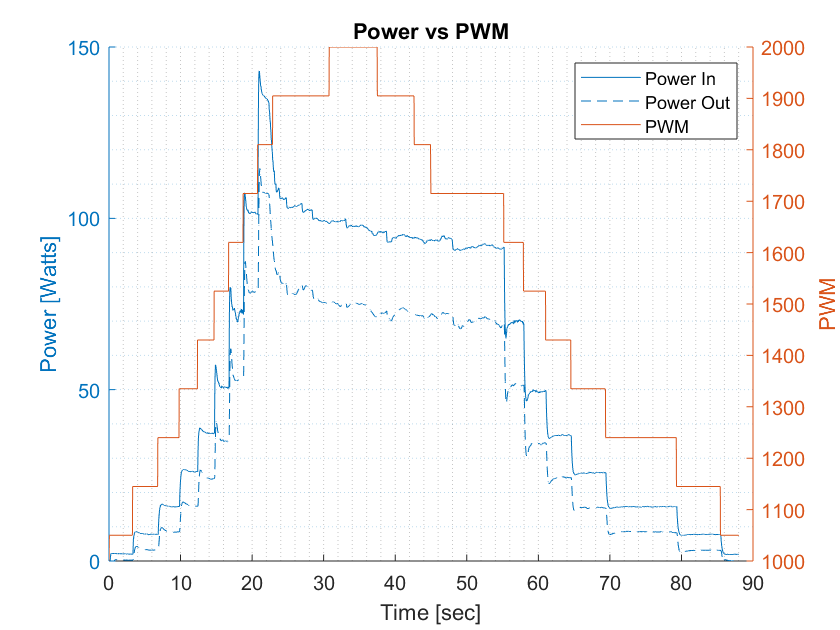


figure(9)
hold on
yyaxis left
plot(time(1:3330),P_in_W(1:3330), time(1:3330), P_out_W(1:3330));
ylabel('Power [Watts]');
legend('Power In', 'Power Out')
yyaxis right
plot(time(1:3330), PWM(1:3330), 'DisplayName','PWM');
ylabel('PWM');
title('Power vs PWM');
xlabel('Time [sec]');
grid('minor');
hold off

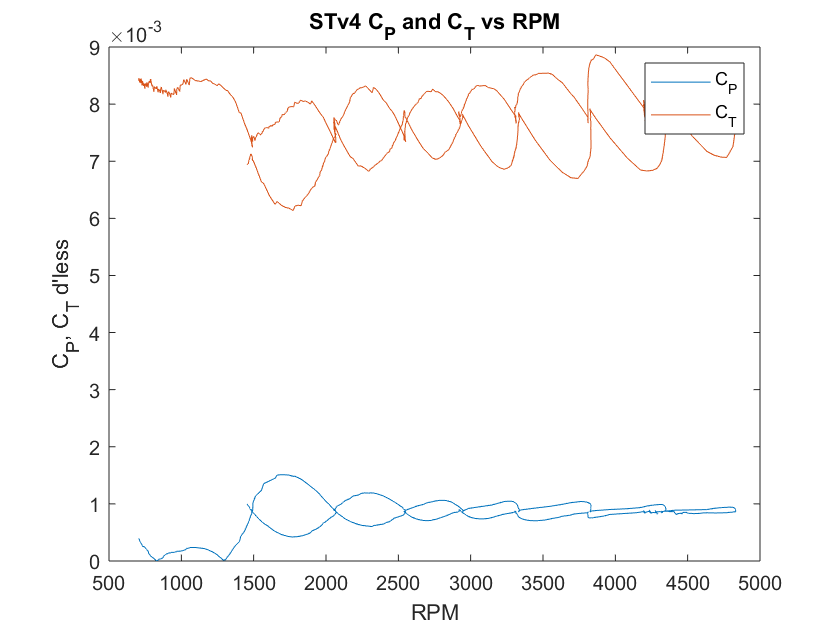


figure(10)
plot(rot_speed_rpm(200:3330), C_P(200:3330), rot_speed_rpm(200:3330), C_T(200:3330));
title('STv4 C_P and C_T vs RPM'); legend('C_P', 'C_T');
xlabel('RPM'); ylabel("C_P, C_T d'less")

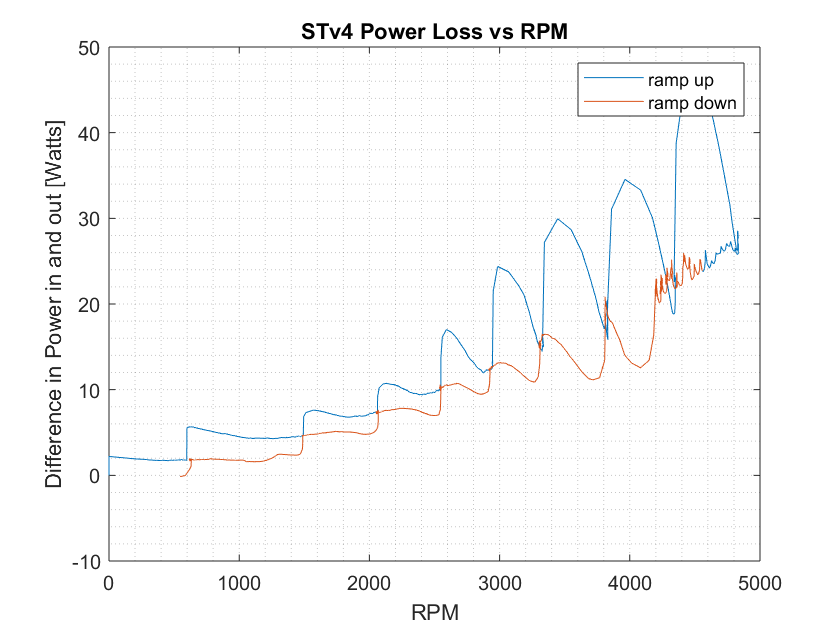


figure(11)
plot(rot_speed_rpm(1:900), P_diff(1:900), rot_speed_rpm(900:end), P_diff(900:end));
xlabel('RPM'); ylabel('Difference in Power in and out [Watts]');
legend('ramp up','ramp down');
title('STv4 Power Loss vs RPM'); grid('minor');

## Comparing Data to Momentum Theory

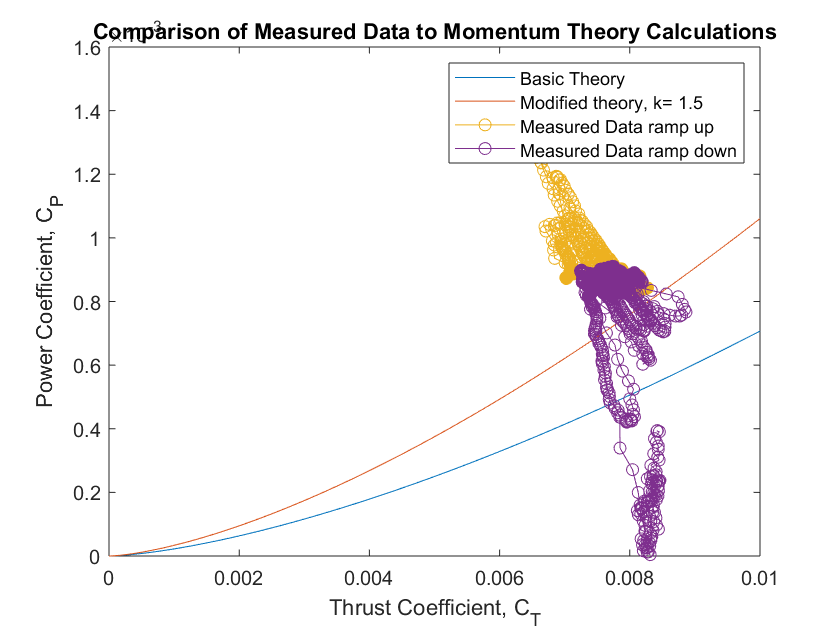

k = 1.5;
C_T_theory = linspace(0, 0.01, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(100)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T(200:900), C_P(200:900), 'o-', C_T(900:3330), C_P(900:3330), 'o-');
title('Comparison of Measured Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.5', 'Measured Data ramp up', 'Measured Data ramp down')